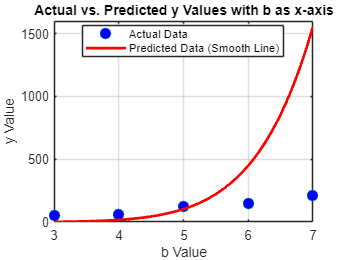

% Data
a = [2; 3; 4; 5; 6];   % values of a
b = [3; 4; 5; 6; 7];   % values of b
y = [50; 60; 120; 150; 210];  % experimental values of y

% Take the logarithm of each variable
A = log(a);  % ln(a)
B = log(b);  % ln(b)
Y = log(y);  % ln(y)

% Combine A and B into a matrix for regression
X = [ones(length(A), 1), A, B];  % Add a column of ones for the intercept

% Perform linear regression to find coefficients
coeffs = X \ Y;  % Solves for [C; x1; x2]

% Extract coefficients
C = coeffs(1);  % intercept, which is ln(k)
x1 = coeffs(2); % coefficient for A (exponent for a)
x2 = coeffs(3); % coefficient for B (exponent for b)

% Calculate the constant k
k = exp(C);

% Set a fixed value of a (e.g., the mean of the a values) for plotting purposes
a_fixed = mean(a);  % This could also be set to a specific value, like a(1)

% Generate a smooth range for b
b_smooth = linspace(min(b), max(b), 100);  % 100 points between min(b) and max(b)

% Calculate predicted y values using the fixed a and smooth b values
y_pred_smooth = k * (a_fixed .^ x1) .* (b_smooth .^ x2);

% Plot the actual y values against b
figure;
plot(b, y, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); % actual y values
hold on;
plot(b_smooth, y_pred_smooth, '-r', 'LineWidth', 2); % smooth predicted y line

% Add labels and title
xlabel('b Value');
ylabel('y Value');
title('Actual vs. Predicted y Values with b as x-axis');
legend('Actual Data', 'Predicted Data (Smooth Line)', 'Location', 'Best');
grid on;
hold off;